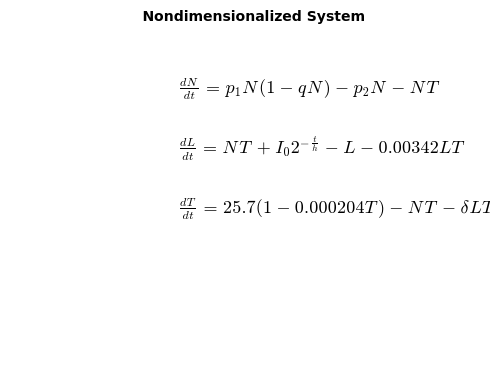

% Nondimensionalized Model %

clc; clear; close all;

figure;
axis off;

%% Define the system of equations using LaTeX %%
eq1 = '$\frac{dN}{dt} = p_1 N (1 - qN) - p_2 N - N T$';
eq2 = '$\frac{dL}{dt} = N T + I_0 2^{-\frac{t}{h}} - L - 0.00342 L T$';
eq3 = '$\frac{dT}{dt} = 25.7(1 - 0.000204 T) - N T - \delta L T$';

%% Display the equations %%
text(0.3, 0.8, eq1, 'Interpreter', 'latex', 'FontSize', 14);
text(0.3, 0.6, eq2, 'Interpreter', 'latex', 'FontSize', 14);
text(0.3, 0.4, eq3, 'Interpreter', 'latex', 'FontSize', 14);

title('Nondimensionalized System');

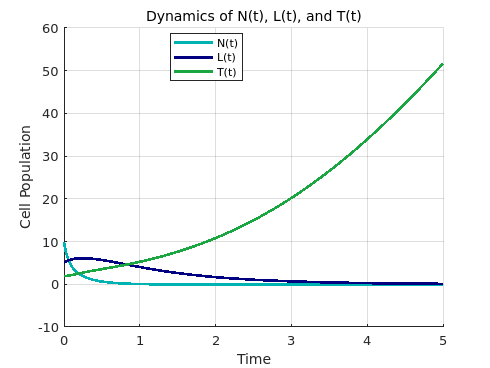



%% Core Parameters %%
P1 = 1;          
q = 1;           
P2 = 1;          
h = 1;
delta = 1;           
I0 = 1;   

%% Tuning Parameters %%
T_param1 = 0.00342; 
T_param2 = 25.7;   
T_param3 = 0.000204;              

%% Initial conditions %%
N0 = 10;
L0 = 5;
T0 = 2;
y0 = [N0; L0; T0];  

%% Time span %%
tspan = [0 5];

%% Solve using ode45 %%
[t, y] = ode45(@(t, y) systemODEs(t, y, P1, q, P2, T_param1, T_param2, T_param3, delta, h, I0), tspan, y0);

N = y(:,1);
L = y(:,2);
T = y(:,3);

%% Plot the results %%
figure; 
hold on;
plot(t, N, 'Color', [0, 0.7, 0.7], 'LineWidth', 2);  
plot(t, L, 'Color', [0, 0, 0.5], 'LineWidth', 2);    
plot(t, T, 'Color', [0.10 0.65 0.25], 'LineWidth', 2); 
hold off;

xlabel('Time');
ylabel('Cell Population');
title('Dynamics of N(t), L(t), and T(t)', 'FontWeight', 'normal');
legend('N(t)', 'L(t)', 'T(t)', 'Location', 'Best');
grid on;

function dydt = systemODEs(t, y, P1, q, P2, T_param1, T_param2, T_param3, delta, h, I0)
    N = y(1);
    L = y(2);   
    T = y(3);
    
    dNdt = P1 * N * (1 - q * N) - P2 * N - N * T;
    dLdt = N * T + I0 * 2^(-t / h) - L - T_param1 * L * T;  
    dTdt = T_param2 * (1 - T_param3 * T) - N * T - delta * L * T;
    
    dydt = [dNdt; dLdt; dTdt];
end
